# Passive Band-Pass and Band-Stop Filters – Theory, Circuit Analysis, and Response Characteristics

**MATLAB Tutorial for Undergraduate Engineering Students**

Based on: Chapter 15 - Active Filters (Floyd's Electronic Devices)

Author: Kessad Mohamed Dhia Eddine

Github: DhiaKessad

Objective: This comprehensive tutorial covers passive band-pass and band-stop filter theory, including RLC configurations, frequency response characteristics (Butterworth, Chebyshev, Bessel), quality factor, bandwidth calculations, time-domain behavior, and MATLAB modeling.

## 1. Introduction to Band-Pass and Band-Stop Filters

**What is a Band-Pass Filter?**

According to Floyd's textbook (Section 15-1):

A band-pass filter passes all signals lying within a band between a lower frequency limit and an upper frequency limit, and essentially rejects all other frequencies that are outside this specified band.

**What is a Band-Stop Filter?**

A band-stop filter (also known as notch, band-reject, or band-elimination filter) operates opposite to a band-pass filter. Frequencies within a certain bandwidth are rejected, while frequencies outside the bandwidth are passed.

**Key Applications:**

**Band-Pass Filters:**

- Radio and communication receivers (channel selection)

- Audio equalizers (tone control in specific frequency bands)

- Biomedical instrumentation (isolating specific physiological signals)

- Spectrum analyzers

- Interference rejection in mixed-signal environments

- Resonant circuits in oscillators

**Band-Stop Filters:**

- 60 Hz (50 Hz) power line interference removal

- Notching out specific interfering frequencies

- Audio feedback suppression

- Harmonic rejection in power systems

- EMI/RFI filtering

## 2. Band-Pass Filter Fundamentals

**Key Parameters and Definitions (from Floyd's Section 15-1)**

**Bandwidth (BW):**

The bandwidth is defined as the difference between the upper critical frequency (fc2) and the lower critical frequency (fc1):


$$BW = f_{c2} - f_{c1}$$


**Critical Frequencies:**

The critical frequencies are the points at which the response curve is 70.7% (or -3 dB) of its maximum value.

**Center Frequency (f0):**

The frequency about which the passband is centered, defined as the geometric mean of the critical frequencies:


$$f_0 = \sqrt{f_{c1} \cdot f_{c2}}$$


Note: This is the GEOMETRIC mean, not arithmetic mean!

**Quality Factor (Q):**

From Floyd's Equation 15-4, the quality factor is the ratio of the center frequency to the bandwidth:


$$Q = \frac{f_0}{BW}$$


The value of Q is an indication of the selectivity of a band-pass filter. The higher the value of Q, the narrower the bandwidth and the better the selectivity for a given value of f0.

**Filter Classification:**

- Narrow-band filter: Q > 10

- Wide-band filter: Q < 10

**Relationship with Damping Factor:**


$$Q = \frac{1}{DF}$$


where DF is the damping factor.

## 3. Series RLC Band-Pass Filter

**Circuit Configuration**

The series RLC circuit creates a band-pass filter when the output is taken across the resistor:

Circuit Topology:

Alternative: Output across R in series RLC

**Key Principle:**

- At low frequencies: Capacitor has high impedance (blocks signal)

- At resonance (f0): Impedances of L and C cancel, only R remains

- At high frequencies: Inductor has high impedance (blocks signal)

- Maximum output occurs at resonant frequency

**Transfer Function Derivation**

Total impedance:


$$Z_{total} = R + sL + \frac{1}{sC}$$


Output voltage (across R):


$$V_{out} = V_{in} \cdot \frac{R}{R + sL + \frac{1}{sC}}$$


Transfer function:


$$H(s) = \frac{R}{R + sL + \frac{1}{sC}}$$


Multiplying by sC:


$$H(s) = \frac{sRC}{s^2LC + sRC + 1}$$


Standard form (dividing by LC):


$$H(s) = \frac{\frac{R}{L}s}{s^2 + \frac{R}{L}s + \frac{1}{LC}}$$


Or in terms of ω0 and Q:


$$H(s) = \frac{\frac{\omega_0}{Q}s}{s^2 + \frac{\omega_0}{Q}s + \omega_0^2}$$


**Resonant Frequency (Center Frequency)**


$$f_0 = \frac{1}{2\pi\sqrt{LC}}$$


**Quality Factor**


$$Q = \frac{1}{R}\sqrt{\frac{L}{C}} = \frac{\omega_0 L}{R} = \frac{1}{\omega_0 RC}$$


**Bandwidth**


$$BW = \frac{f_0}{Q} = \frac{R}{2\pi L}$$


**Critical Frequencies**


$$f_{c1} = f_0\left(\sqrt{1 + \frac{1}{4Q^2}} - \frac{1}{2Q}\right)$$



$$f_{c2} = f_0\left(\sqrt{1 + \frac{1}{4Q^2}} + \frac{1}{2Q}\right)$$


## 4. MATLAB Implementation - Series RLC Band-Pass Filter

% Design a band-pass filter for audio application (voice communications)
% Center frequency: 1 kHz, Bandwidth: 200 Hz (Q = 5)

f0_bp = 1000;            % Center frequency = 1 kHz
BW_bp = 200;             % Bandwidth = 200 Hz
Q_bp = f0_bp / BW_bp;    % Quality factor

fprintf('SERIES RLC BAND-PASS FILTER DESIGN:\n');

SERIES RLC BAND-PASS FILTER DESIGN:


fprintf('=====================================\n');

fprintf('Target center frequency f0 = %.1f Hz\n', f0_bp);

Target center frequency f0 = 1000.0 Hz


fprintf('Target bandwidth BW = %.1f Hz\n', BW_bp);

Target bandwidth BW = 200.0 Hz


fprintf('Target quality factor Q = %.2f\n', Q_bp);

Target quality factor Q = 5.00


fprintf('Filter classification: %s\n\n', char(ternary(Q_bp > 10, 'Narrow-band', 'Wide-band')));

Filter classification: Wide-band




% Select component values
C_bp = 100e-9;           % Choose C = 100 nF
L_bp = 1 / ((2*pi*f0_bp)^2 * C_bp);
R_bp = (1/Q_bp) * sqrt(L_bp/C_bp);

% Calculate actual parameters
f0_actual = 1 / (2*pi*sqrt(L_bp*C_bp));
Q_actual = (1/R_bp) * sqrt(L_bp/C_bp);
BW_actual = f0_actual / Q_actual;

% Calculate critical frequencies
term = sqrt(1 + 1/(4*Q_actual^2));
fc1_bp = f0_actual * (term - 1/(2*Q_actual));
fc2_bp = f0_actual * (term + 1/(2*Q_actual));

fprintf('COMPONENT VALUES:\n');

COMPONENT VALUES:


fprintf('Resistance R = %.2f Ω\n', R_bp);

Resistance R = 318.31 Ω


fprintf('Inductance L = %.3f mH\n', L_bp*1e3);

Inductance L = 253.303 mH


fprintf('Capacitance C = %.2f nF\n', C_bp*1e9);

Capacitance C = 100.00 nF


fprintf('\nACTUAL PERFORMANCE:\n');


ACTUAL PERFORMANCE:


fprintf('Center frequency f0 = %.2f Hz\n', f0_actual);

Center frequency f0 = 1000.00 Hz


fprintf('Quality factor Q = %.2f\n', Q_actual);

Quality factor Q = 5.00


fprintf('Bandwidth BW = %.2f Hz\n', BW_actual);

Bandwidth BW = 200.00 Hz


fprintf('Lower critical frequency fc1 = %.2f Hz\n', fc1_bp);

Lower critical frequency fc1 = 904.99 Hz


fprintf('Upper critical frequency fc2 = %.2f Hz\n', fc2_bp);

Upper critical frequency fc2 = 1104.99 Hz


fprintf('Verification: fc2 - fc1 = %.2f Hz\n', fc2_bp - fc1_bp);

Verification: fc2 - fc1 = 200.00 Hz


fprintf('Geometric mean √(fc1×fc2) = %.2f Hz\n\n', sqrt(fc1_bp*fc2_bp));

Geometric mean √(fc1×fc2) = 1000.00 Hz




% Create transfer function
s = tf('s');
w0_bp = 2*pi*f0_actual;
H_series_bp = (w0_bp/Q_actual)*s / (s^2 + (w0_bp/Q_actual)*s + w0_bp^2);

fprintf('Transfer Function H(s):\n');

Transfer Function H(s):


disp(H_series_bp);

  tf with properties:

       Numerator: {[0 1.2566e+03 0]}
     Denominator: {[1 1.2566e+03 3.9478e+07]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## 5. Frequency Response Analysis - Series RLC Band-Pass

% Generate frequency vector
f = logspace(1, 5, 2000);    % 10 Hz to 100 kHz
w = 2 * pi * f;

% Compute frequency response
[mag_bp, phase_bp] = bode(H_series_bp, w);
mag_bp = squeeze(mag_bp);
phase_bp = squeeze(phase_bp);
mag_dB_bp = 20 * log10(mag_bp);

% Find actual -3dB points
[~, idx_peak] = max(mag_bp);
mag_peak = mag_bp(idx_peak);
mag_3db = mag_peak / sqrt(2);

idx_lower = find(mag_bp(1:idx_peak) >= mag_3db, 1, 'first');
idx_upper = find(mag_bp(idx_peak:end) <= mag_3db, 1, 'first') + idx_peak - 1;

fc1_measured = f(idx_lower);
fc2_measured = f(idx_upper);
BW_measured = fc2_measured - fc1_measured;

fprintf('MEASURED FROM BODE PLOT:\n');

MEASURED FROM BODE PLOT:


fprintf('Lower -3dB frequency = %.2f Hz\n', fc1_measured);

Lower -3dB frequency = 905.69 Hz


fprintf('Upper -3dB frequency = %.2f Hz\n', fc2_measured);

Upper -3dB frequency = 1109.23 Hz


fprintf('Measured bandwidth = %.2f Hz\n', BW_measured);

Measured bandwidth = 203.54 Hz


fprintf('Measured Q = %.2f\n\n', f0_actual/BW_measured);

Measured Q = 4.91



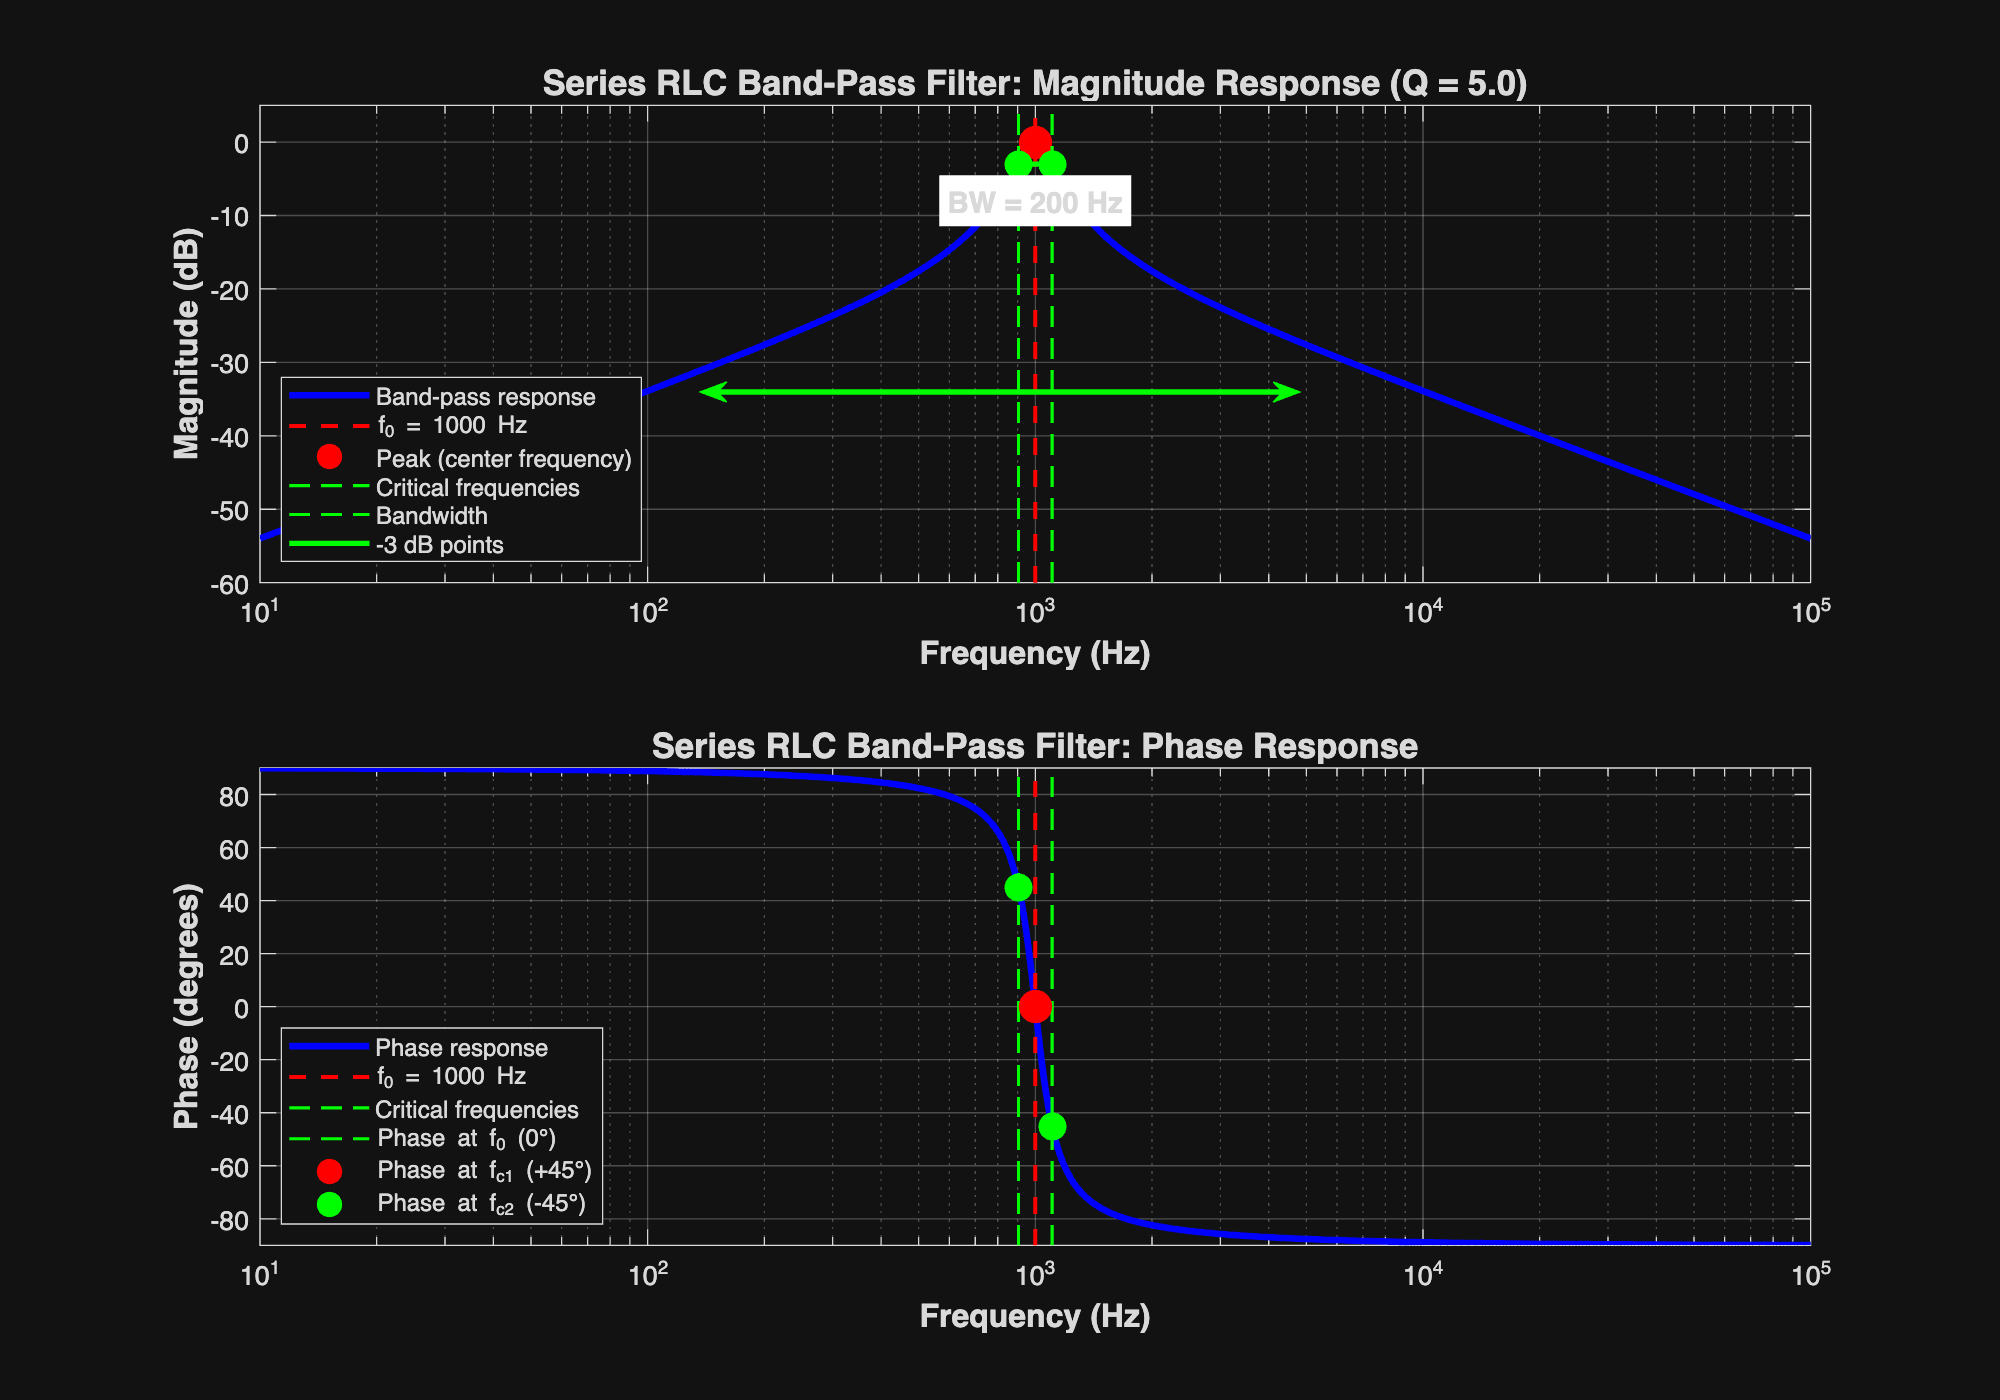


% Create comprehensive Bode plot
figure('Position', [100, 100, 1000, 700]);

% Magnitude plot
subplot(2, 1, 1);
semilogx(f, mag_dB_bp, 'b-', 'LineWidth', 2.5);
hold on;

% Mark center frequency
semilogx([f0_actual, f0_actual], [-60, 5], 'r--', 'LineWidth', 1.5);
plot(f0_actual, mag_dB_bp(idx_peak), 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r');

% Mark -3dB bandwidth
semilogx([fc1_bp, fc1_bp], [-60, 5], 'g--', 'LineWidth', 1.2);
semilogx([fc2_bp, fc2_bp], [-60, 5], 'g--', 'LineWidth', 1.2);
semilogx([fc1_bp, fc2_bp], [mag_dB_bp(idx_peak)-3, mag_dB_bp(idx_peak)-3], ...
         'g-', 'LineWidth', 2);
plot(fc1_bp, mag_dB_bp(idx_peak)-3, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot(fc2_bp, mag_dB_bp(idx_peak)-3, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');

% Add bandwidth annotation
annotation('doublearrow', [0.35, 0.65], [0.72, 0.72], 'LineWidth', 2, 'Color', 'g');
text(f0_actual, mag_dB_bp(idx_peak)-8, sprintf('BW = %.0f Hz', BW_actual), ...
     'FontSize', 11, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', ...
     'BackgroundColor', 'white');

hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title(sprintf('Series RLC Band-Pass Filter: Magnitude Response (Q = %.1f)', Q_actual), ...
      'FontSize', 13, 'FontWeight', 'bold');
legend('Band-pass response', sprintf('f_0 = %.0f Hz', f0_actual), ...
       'Peak (center frequency)', 'Critical frequencies', 'Bandwidth', ...
       '-3 dB points', 'Location', 'southwest', 'FontSize', 9);
ylim([-60, 5]);
xlim([f(1), f(end)]);

% Phase plot
subplot(2, 1, 2);
semilogx(f, phase_bp, 'b-', 'LineWidth', 2.5);
hold on;
semilogx([f0_actual, f0_actual], [-90, 90], 'r--', 'LineWidth', 1.5);
semilogx([fc1_bp, fc1_bp], [-90, 90], 'g--', 'LineWidth', 1.2);
semilogx([fc2_bp, fc2_bp], [-90, 90], 'g--', 'LineWidth', 1.2);
plot(f0_actual, 0, 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r');
plot(fc1_bp, 45, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot(fc2_bp, -45, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Phase (degrees)', 'FontSize', 12, 'FontWeight', 'bold');
title('Series RLC Band-Pass Filter: Phase Response', 'FontSize', 13, 'FontWeight', 'bold');
legend('Phase response', sprintf('f_0 = %.0f Hz', f0_actual), ...
       'Critical frequencies', 'Phase at f_0 (0°)', 'Phase at f_{c1} (+45°)', ...
       'Phase at f_{c2} (-45°)', 'Location', 'southwest', 'FontSize', 9);
ylim([-90, 90]);
xlim([f(1), f(end)]);

## Analysis of Band-Pass Filter Response

**Frequency Domain Observations:**

- **Below fc1 (stopband):** Attenuation increases as frequency decreases

- **At fc1:** Magnitude is -3 dB below peak, phase = +45°

- **At f0 (center):** Maximum gain (peak response), phase = 0°

- **At fc2:** Magnitude is -3 dB below peak, phase = -45°

- **Above fc2 (stopband):** Attenuation increases as frequency increases

**Phase Characteristics:**

- Below f0: Phase is positive (leading, capacitive dominance)

- At f0: Phase is exactly 0° (resonance - L and C cancel)

- Above f0: Phase is negative (lagging, inductive dominance)

- Phase transition from +90° to -90° (total 180° swing)

**Quality Factor Effects:**

- Higher Q → Narrower bandwidth → Better selectivity

- Lower Q → Wider bandwidth → Less selective

- Q = 5 indicates moderate selectivity (wide-band filter)

**Symmetry:**

Note that the response is symmetric on a logarithmic frequency scale around f0.

## 6. Effect of Quality Factor (Q) on Band-Pass Response

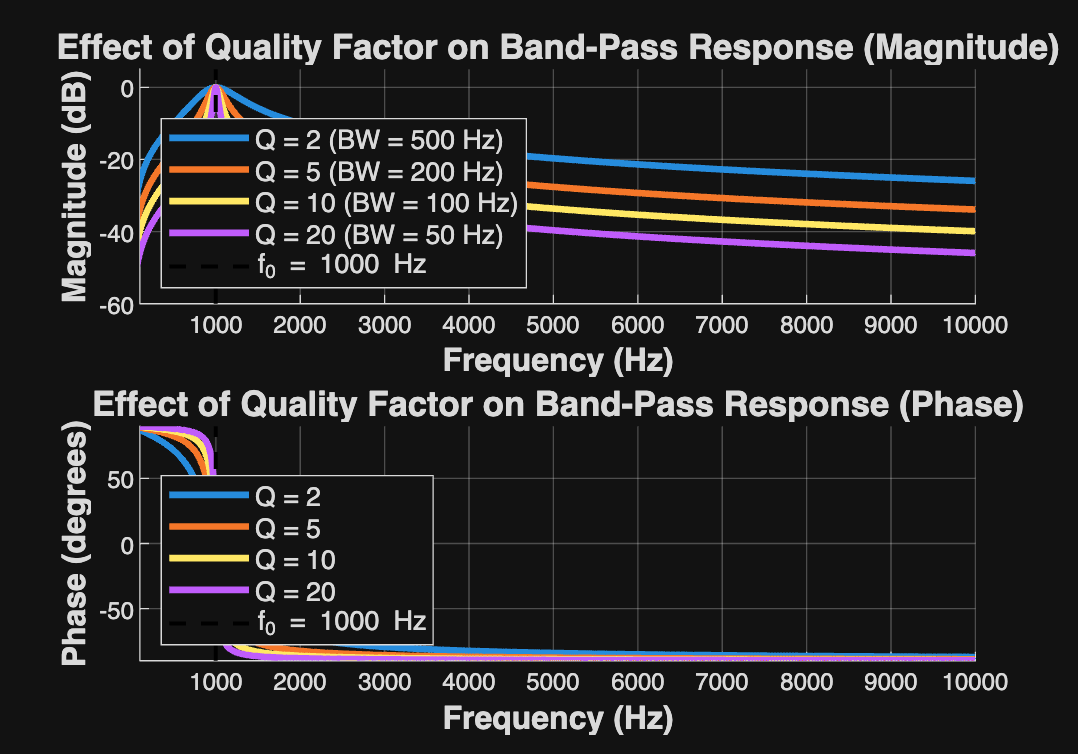

% Create multiple band-pass filters with different Q values
Q_values = [2, 5, 10, 20];
colors = lines(length(Q_values));

figure('Position', [100, 100, 1000, 700]);

% Magnitude comparison
subplot(2, 1, 1);
hold on;
for i = 1:length(Q_values)
    Q_test = Q_values(i);
    R_test = (1/Q_test) * sqrt(L_bp/C_bp);
    H_test = (w0_bp/Q_test)*s / (s^2 + (w0_bp/Q_test)*s + w0_bp^2);
    
    [mag_test, ~] = bode(H_test, w);
    mag_test = squeeze(mag_test);
    mag_dB_test = 20 * log10(mag_test);
    
    BW_test = f0_actual / Q_test;
    
    semilogx(f, mag_dB_test, 'LineWidth', 2.5, 'Color', colors(i,:), ...
             'DisplayName', sprintf('Q = %.0f (BW = %.0f Hz)', Q_test, BW_test));
end

% Mark center frequency
semilogx([f0_actual, f0_actual], [-60, 5], 'k--', 'LineWidth', 1.5, ...
         'DisplayName', sprintf('f_0 = %.0f Hz', f0_actual));
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Effect of Quality Factor on Band-Pass Response (Magnitude)', ...
      'FontSize', 13, 'FontWeight', 'bold');
legend('Location', 'southwest', 'FontSize', 10);
ylim([-60, 5]);
xlim([100, 10000]);

% Phase comparison
subplot(2, 1, 2);
hold on;
for i = 1:length(Q_values)
    Q_test = Q_values(i);
    R_test = (1/Q_test) * sqrt(L_bp/C_bp);
    H_test = (w0_bp/Q_test)*s / (s^2 + (w0_bp/Q_test)*s + w0_bp^2);
    
    [~, phase_test] = bode(H_test, w);
    phase_test = squeeze(phase_test);
    
    semilogx(f, phase_test, 'LineWidth', 2.5, 'Color', colors(i,:), ...
             'DisplayName', sprintf('Q = %.0f', Q_values(i)));
end

semilogx([f0_actual, f0_actual], [-90, 90], 'k--', 'LineWidth', 1.5, ...
         'DisplayName', sprintf('f_0 = %.0f Hz', f0_actual));
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Phase (degrees)', 'FontSize', 12, 'FontWeight', 'bold');
title('Effect of Quality Factor on Band-Pass Response (Phase)', ...
      'FontSize', 13, 'FontWeight', 'bold');
legend('Location', 'southwest', 'FontSize', 10);
ylim([-90, 90]);
xlim([100, 10000]);

## Quality Factor Analysis

**Key Observations:**

- **Q = 2 (wide-band):** Very broad response, low selectivity, gentle slopes

- **Q = 5 (moderate):** Moderate bandwidth, reasonable selectivity

- **Q = 10 (narrow-band):** Narrow bandwidth, high selectivity, steep slopes

- **Q = 20 (very narrow-band):** Very narrow bandwidth, excellent selectivity

**Trade-offs:**

- Higher Q provides better frequency selectivity

- Higher Q has steeper phase transition around f0

- Higher Q is more sensitive to component tolerances

- Higher Q may have lower maximum gain (resistor dissipation)

**From Floyd's Definition:**

- Narrow-band filter: Q > 10 (sharp selectivity)

- Wide-band filter: Q < 10 (broad response)

## 7. Time-Domain Response - Band-Pass Filter

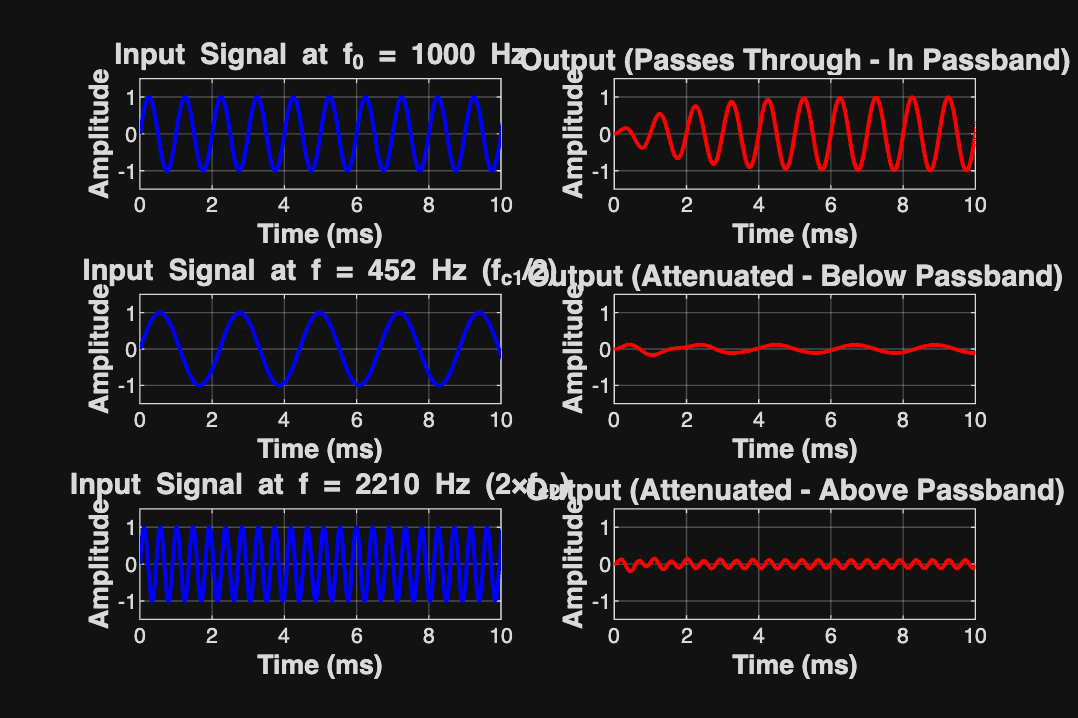

% Create input signals for time-domain analysis
t = linspace(0, 0.05, 5000);  % 50 ms time window

% Signal 1: At center frequency (f0) - should pass
signal_f0 = sin(2*pi*f0_actual*t);

% Signal 2: Below passband (fc1/2) - should be attenuated
signal_low = sin(2*pi*(fc1_bp/2)*t);

% Signal 3: Above passband (2*fc2) - should be attenuated
signal_high = sin(2*pi*(2*fc2_bp)*t);

% Simulate responses
[y_f0, t_f0] = lsim(H_series_bp, signal_f0, t);
[y_low, t_low] = lsim(H_series_bp, signal_low, t);
[y_high, t_high] = lsim(H_series_bp, signal_high, t);

% Plot time-domain responses
figure('Position', [100, 100, 1200, 800]);

% Input at center frequency
subplot(3, 2, 1);
plot(t*1e3, signal_f0, 'b-', 'LineWidth', 1.5);
grid on;
xlabel('Time (ms)', 'FontSize', 10, 'FontWeight', 'bold');
ylabel('Amplitude', 'FontSize', 10, 'FontWeight', 'bold');
title(sprintf('Input Signal at f_0 = %.0f Hz', f0_actual), 'FontSize', 11, 'FontWeight', 'bold');
ylim([-1.5, 1.5]);
xlim([0, 10]);

subplot(3, 2, 2);
plot(t_f0*1e3, y_f0, 'r-', 'LineWidth', 1.5);
grid on;
xlabel('Time (ms)', 'FontSize', 10, 'FontWeight', 'bold');
ylabel('Amplitude', 'FontSize', 10, 'FontWeight', 'bold');
title('Output (Passes Through - In Passband)', 'FontSize', 11, 'FontWeight', 'bold');
ylim([-1.5, 1.5]);
xlim([0, 10]);

% Input below passband
subplot(3, 2, 3);
plot(t*1e3, signal_low, 'b-', 'LineWidth', 1.5);
grid on;
xlabel('Time (ms)', 'FontSize', 10, 'FontWeight', 'bold');
ylabel('Amplitude', 'FontSize', 10, 'FontWeight', 'bold');
title(sprintf('Input Signal at f = %.0f Hz (f_{c1}/2)', fc1_bp/2), ...
      'FontSize', 11, 'FontWeight', 'bold');
ylim([-1.5, 1.5]);
xlim([0, 10]);

subplot(3, 2, 4);
plot(t_low*1e3, y_low, 'r-', 'LineWidth', 1.5);
grid on;
xlabel('Time (ms)', 'FontSize', 10, 'FontWeight', 'bold');
ylabel('Amplitude', 'FontSize', 10, 'FontWeight', 'bold');
title('Output (Attenuated - Below Passband)', 'FontSize', 11, 'FontWeight', 'bold');
ylim([-1.5, 1.5]);
xlim([0, 10]);

% Input above passband
subplot(3, 2, 5);
plot(t*1e3, signal_high, 'b-', 'LineWidth', 1.5);
grid on;
xlabel('Time (ms)', 'FontSize', 10, 'FontWeight', 'bold');
ylabel('Amplitude', 'FontSize', 10, 'FontWeight', 'bold');
title(sprintf('Input Signal at f = %.0f Hz (2×f_{c2})', 2*fc2_bp), ...
      'FontSize', 11, 'FontWeight', 'bold');
ylim([-1.5, 1.5]);
xlim([0, 10]);

subplot(3, 2, 6);
plot(t_high*1e3, y_high, 'r-', 'LineWidth', 1.5);
grid on;
xlabel('Time (ms)', 'FontSize', 10, 'FontWeight', 'bold');
ylabel('Amplitude', 'FontSize', 10, 'FontWeight', 'bold');
title('Output (Attenuated - Above Passband)', 'FontSize', 11, 'FontWeight', 'bold');
ylim([-1.5, 1.5]);
xlim([0, 10]);

## Time-Domain Analysis

**Observations:**

- **Signal at f0:** Passes through with maximum amplitude (in passband)

- **Signal below fc1:** Heavily attenuated (outside passband)

- **Signal above fc2:** Heavily attenuated (outside passband)

**Physical Interpretation:**

The band-pass filter acts as a "frequency window" that only allows signals within the bandwidth (fc1 to fc2) to pass with minimal attenuation. All other frequencies are significantly reduced.

This selective behavior makes band-pass filters essential for:

- Radio tuning (selecting desired station)

- Interference rejection (removing unwanted frequencies)

- Signal extraction (isolating specific frequency components)

## 8. Parallel RLC Band-Pass Filter

**Circuit Configuration**

A parallel RLC configuration can also create a band-pass response:

Circuit Topology:

For a simple parallel RLC with output across the parallel combination:

**Transfer Function**

For parallel RLC with series input resistance:


$$H(s) = \frac{\frac{1}{R_s C}s}{s^2 + \frac{1}{R_p C}s + \frac{1}{LC}}$$


where Rs is series resistance and Rp is parallel resistance.

**Key Difference from Series RLC:**

- Series: Low impedance at resonance (maximum current, maximum voltage across R)

- Parallel: High impedance at resonance (minimum current, maximum voltage across tank)

## 9. Wide-Band Band-Pass Filter (Cascaded High-Pass and Low-Pass)

**Alternative Configuration**

A wide-band band-pass filter (Q < 10) can be created by cascading a high-pass filter followed by a low-pass filter:

**Design Requirements:**

- fc(high-pass) < fc(low-pass)

- fc(high-pass) = fc1 (lower critical frequency)

- fc(low-pass) = fc2 (upper critical frequency)

- f0 = √(fc1 × fc2)

**Implementation:**

% Design wide-band BP using cascaded approach
fc1_cascade = 500;       % Lower cutoff = 500 Hz
fc2_cascade = 5000;      % Upper cutoff = 5 kHz
f0_cascade = sqrt(fc1_cascade * fc2_cascade);
BW_cascade = fc2_cascade - fc1_cascade;
Q_cascade = f0_cascade / BW_cascade;

fprintf('CASCADED HIGH-PASS + LOW-PASS BAND-PASS FILTER:\n');

CASCADED HIGH-PASS + LOW-PASS BAND-PASS FILTER:


fprintf('==================================================\n');

fprintf('Lower cutoff frequency fc1 = %.0f Hz\n', fc1_cascade);

Lower cutoff frequency fc1 = 500 Hz


fprintf('Upper cutoff frequency fc2 = %.0f Hz\n', fc2_cascade);

Upper cutoff frequency fc2 = 5000 Hz


fprintf('Center frequency f0 = %.0f Hz\n', f0_cascade);

Center frequency f0 = 1581 Hz


fprintf('Bandwidth BW = %.0f Hz\n', BW_cascade);

Bandwidth BW = 4500 Hz


fprintf('Quality factor Q = %.2f (%s)\n\n', Q_cascade, ...
        char(ternary(Q_cascade > 10, 'Narrow-band', 'Wide-band')));

Quality factor Q = 0.35 (Wide-band)




% Design high-pass stage (RC)
C_hp_stage = 100e-9;
R_hp_stage = 1 / (2*pi*fc1_cascade*C_hp_stage);

% Design low-pass stage (RC)
R_lp_stage = 10e3;
C_lp_stage = 1 / (2*pi*fc2_cascade*R_lp_stage);

fprintf('HIGH-PASS STAGE:\n');

HIGH-PASS STAGE:


fprintf('R = %.2f kΩ, C = %.2f nF\n', R_hp_stage/1e3, C_hp_stage/1e9);

R = 3.18 kΩ, C = 0.00 nF


fprintf('\nLOW-PASS STAGE:\n');


LOW-PASS STAGE:


fprintf('R = %.2f kΩ, C = %.2f nF\n\n', R_lp_stage/1e3, C_lp_stage/1e9);

R = 10.00 kΩ, C = 0.00 nF



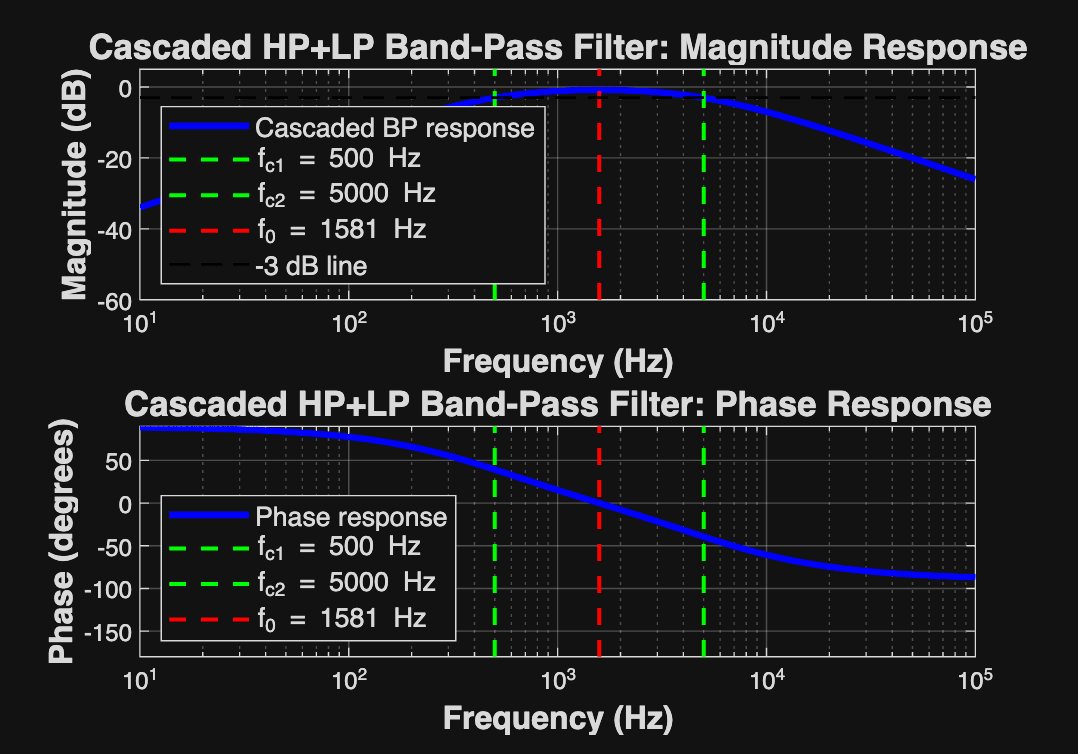


% Create transfer functions
H_hp_stage = (s*R_hp_stage*C_hp_stage) / (1 + s*R_hp_stage*C_hp_stage);
H_lp_stage = 1 / (1 + s*R_lp_stage*C_lp_stage);
H_cascade_bp = H_hp_stage * H_lp_stage;

% Compute response
[mag_cascade, phase_cascade] = bode(H_cascade_bp, w);
mag_cascade = squeeze(mag_cascade);
phase_cascade = squeeze(phase_cascade);
mag_dB_cascade = 20 * log10(mag_cascade);

% Plot cascaded response
figure('Position', [100, 100, 1000, 700]);

subplot(2, 1, 1);
semilogx(f, mag_dB_cascade, 'b-', 'LineWidth', 2.5);
hold on;
semilogx([fc1_cascade, fc1_cascade], [-60, 5], 'g--', 'LineWidth', 1.5);
semilogx([fc2_cascade, fc2_cascade], [-60, 5], 'g--','LineWidth', 1.5);
semilogx([f0_cascade, f0_cascade], [-60, 5], 'r--', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [-3, -3], 'k--', 'LineWidth', 1);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Cascaded HP+LP Band-Pass Filter: Magnitude Response', ...
'FontSize', 13, 'FontWeight', 'bold');
legend('Cascaded BP response', sprintf('f_{c1} = %.0f Hz', fc1_cascade), ...
sprintf('f_{c2} = %.0f Hz', fc2_cascade), sprintf('f_0 = %.0f Hz', f0_cascade), ...
'-3 dB line', 'Location', 'southwest', 'FontSize', 10);
ylim([-60, 5]);
xlim([10, 1e5]);
subplot(2, 1, 2);
semilogx(f, phase_cascade, 'b-', 'LineWidth', 2.5);
hold on;
semilogx([fc1_cascade, fc1_cascade], [-180, 90], 'g--', 'LineWidth', 1.5);
semilogx([fc2_cascade, fc2_cascade], [-180, 90], 'g--', 'LineWidth', 1.5);
semilogx([f0_cascade, f0_cascade], [-180, 90], 'r--', 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Phase (degrees)', 'FontSize', 12, 'FontWeight', 'bold');
title('Cascaded HP+LP Band-Pass Filter: Phase Response', ...
'FontSize', 13, 'FontWeight', 'bold');
legend('Phase response', sprintf('f_{c1} = %.0f Hz', fc1_cascade), ...
sprintf('f_{c2} = %.0f Hz', fc2_cascade), sprintf('f_0 = %.0f Hz', f0_cascade), ...
'Location', 'southwest', 'FontSize', 10);
ylim([-180, 90]);
xlim([10, 1e5]);

## Cascaded Band-Pass Analysis

Advantages of Cascaded HP+LP Configuration:

- Easier to design for wide-band applications (Q < 10)

- Independent control of fc1 and fc2

- No inductors required (uses only R and C)

- Less sensitive to component tolerances

Disadvantages:

- Not suitable for narrow-band applications (Q > 10)

- Requires more components (two filter stages)

- Less symmetrical response compared to RLC

- Loading effects between stages may require buffering

When to Use:

Use cascaded approach when Q < 10 and when avoiding inductors is important. Use RLC approach when Q > 10 or when sharper selectivity is needed.

## 10. Band-Stop (Notch) Filter Fundamentals

Introduction (from Floyd's Section 15-1)

From Floyd's textbook:

"Another category of active filter is the band-stop filter, also known as notch, band-reject, or band-elimination filter. You can think of the operation as opposite to that of the band-pass filter because frequencies within a certain bandwidth are rejected, and frequencies outside the bandwidth are passed."

Key Parameters:

The bandwidth is the band of frequencies between the -3 dB points, just as in the case of the band-pass filter response.

- Center frequency: f0 = √(fc1 × fc2)

- Bandwidth: BW = fc2 - fc1

- Quality factor: Q = f0 / BW

Applications:

- Removing 60 Hz (or 50 Hz) power line interference

- Notching out specific interfering tones

- Eliminating harmonics

- Audio feedback suppression

## 11. Series RLC Band-Stop Filter

**Circuit Configuration**

The series RLC circuit creates a band-stop filter when the output is taken across the series LC combination:

Circuit Topology:

Alternative: Parallel LC in series with R

Output taken across the parallel LC tank.

**Key Principle:**

- At low frequencies: Capacitor blocks (high impedance), signal passes through

- At resonance (f0): LC series has minimum impedance (short), signal blocked

- At high frequencies: Inductor blocks (high impedance), signal passes through

- Minimum output occurs at resonant frequency

**Transfer Function (Parallel LC Configuration)**


$$H(s) = \frac{s^2 + \omega_0^2}{s^2 + \frac{\omega_0}{Q}s + \omega_0^2}$$


where:

- ω0=1LC\omega_0 = \frac{1}{\sqrt{LC}}

% Resonant (notch) angular frequency
% w0 = 1 / sqrt(L*C)

% Quality factor
% Q = R*sqrt(C/L)
%
% *Notch Frequency*
%
% $$f_0 = \frac{1}{2\pi\sqrt{LC}}$$
%
% This is the frequency with maximum attenuation (the notch).

## 12. MATLAB Implementation - Parallel RLC Band-Stop Filter

Design a 60 Hz notch filter for power line interference removal

f0_notch = 60;           % Notch frequency = 60 Hz
Q_notch = 10;            % Quality factor for narrow notch
BW_notch = f0_notch / Q_notch;
fprintf('PARALLEL RLC BAND-STOP (NOTCH) FILTER DESIGN:\n');

PARALLEL RLC BAND-STOP (NOTCH) FILTER DESIGN:


fprintf('==============================================\n');

fprintf('Target notch frequency f0 = %.1f Hz\n', f0_notch);

Target notch frequency f0 = 60.0 Hz


fprintf('Target quality factor Q = %.0f\n', Q_notch);

Target quality factor Q = 10


fprintf('Target bandwidth BW = %.2f Hz\n\n', BW_notch);

Target bandwidth BW = 6.00 Hz



% Select component values
C_notch = 100e-6;        % Choose C = 100 μF
L_notch = 1 / ((2*pi*f0_notch)^2 * C_notch);
R_notch = Q_notch * sqrt(L_notch / C_notch);
% Calculate actual parameters
f0_notch_actual = 1 / (2*pi*sqrt(L_notch*C_notch));
Q_notch_actual = R_notch * sqrt(C_notch / L_notch);
BW_notch_actual = f0_notch_actual / Q_notch_actual;
fprintf('COMPONENT VALUES:\n');

COMPONENT VALUES:


fprintf('Resistance R = %.2f Ω\n', R_notch);

Resistance R = 265.26 Ω


fprintf('Inductance L = %.3f H\n', L_notch);

Inductance L = 0.070 H


fprintf('Capacitance C = %.2f μF\n', C_notch*1e6);

Capacitance C = 100.00 μF


fprintf('\nACTUAL PERFORMANCE:\n');


ACTUAL PERFORMANCE:


fprintf('Notch frequency f0 = %.2f Hz\n', f0_notch_actual);

Notch frequency f0 = 60.00 Hz


fprintf('Quality factor Q = %.2f\n', Q_notch_actual);

Quality factor Q = 10.00


fprintf('Bandwidth BW = %.2f Hz\n', BW_notch_actual);

Bandwidth BW = 6.00 Hz


fprintf('Attenuation at f0: Maximum (notch depth depends on component Q)\n\n');

Attenuation at f0: Maximum (notch depth depends on component Q)



% Create transfer function (band-stop)
w0_notch = 2*pi*f0_notch_actual;
H_notch = (s^2 + w0_notch^2) / (s^2 + (w0_notch/Q_notch_actual)*s + w0_notch^2);
fprintf('Transfer Function H(s):\n');

Transfer Function H(s):


disp(H_notch);

  tf with properties:

       Numerator: {[1 0 1.4212e+05]}
     Denominator: {[1 37.6991 1.4212e+05]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## 13. Frequency Response Analysis - Band-Stop Filter

Generate frequency vector

f_notch = logspace(0, 3, 2000);    % 1 Hz to 1 kHz
w_notch = 2 * pi * f_notch;
% Compute frequency response
[mag_notch, phase_notch] = bode(H_notch, w_notch);
mag_notch = squeeze(mag_notch);
phase_notch = squeeze(phase_notch);
mag_dB_notch = 20 * log10(mag_notch);
% Find notch depth
[min_mag, idx_notch] = min(mag_dB_notch);
f_at_notch = f_notch(idx_notch);
fprintf('MEASURED FROM BODE PLOT:\n');

MEASURED FROM BODE PLOT:


fprintf('Notch frequency = %.2f Hz\n', f_at_notch);

Notch frequency = 60.03 Hz


fprintf('Notch depth = %.2f dB\n\n', min_mag);

Notch depth = -39.21 dB



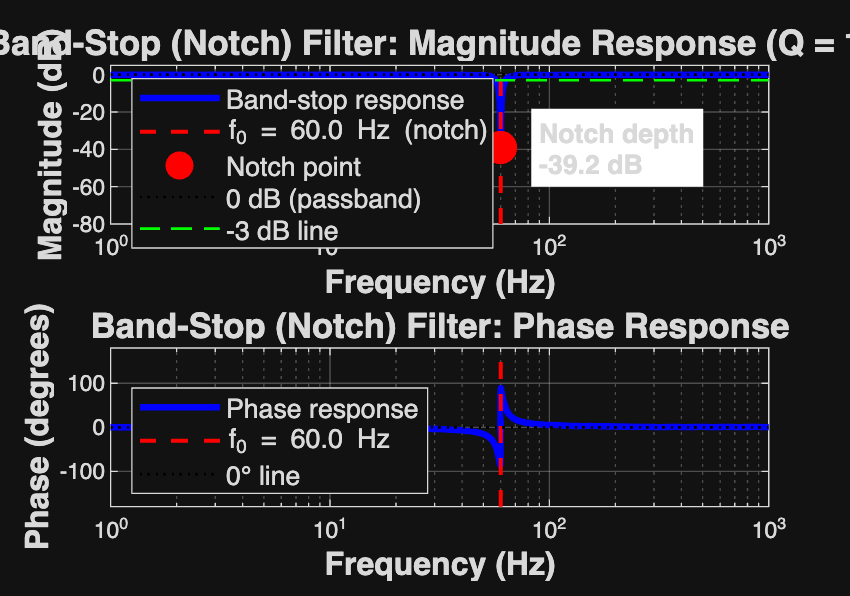

% Create comprehensive Bode plot for notch filter
figure('Position', [100, 100, 1000, 700]);
% Magnitude plot
subplot(2, 1, 1);
semilogx(f_notch, mag_dB_notch, 'b-', 'LineWidth', 2.5);
hold on;
% Mark notch frequency
semilogx([f0_notch_actual, f0_notch_actual], [-80, 5], 'r--', 'LineWidth', 1.5);
plot(f0_notch_actual, min_mag, 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r');
% Mark 0 dB line (passband)
semilogx([f_notch(1), f_notch(end)], [0, 0], 'k:', 'LineWidth', 1);
% Mark -3 dB points
semilogx([f_notch(1), f_notch(end)], [-3, -3], 'g--', 'LineWidth', 1);
% Add notch annotation
text(f0_notch_actual*1.5, min_mag, sprintf('Notch depth\n%.1f dB', min_mag), ...
'FontSize', 10, 'FontWeight', 'bold', 'BackgroundColor', 'white');
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title(sprintf('Band-Stop (Notch) Filter: Magnitude Response (Q = %.0f)', Q_notch_actual), ...
'FontSize', 13, 'FontWeight', 'bold');
legend('Band-stop response', sprintf('f_0 = %.1f Hz (notch)', f0_notch_actual), ...
'Notch point', '0 dB (passband)', '-3 dB line', ...
'Location', 'southwest', 'FontSize', 10);
ylim([-80, 5]);
xlim([f_notch(1), f_notch(end)]);
% Phase plot
subplot(2, 1, 2);
semilogx(f_notch, phase_notch, 'b-', 'LineWidth', 2.5);
hold on;
semilogx([f0_notch_actual, f0_notch_actual], [-180, 180], 'r--', 'LineWidth', 1.5);
semilogx([f_notch(1), f_notch(end)], [0, 0], 'k:', 'LineWidth', 1);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Phase (degrees)', 'FontSize', 12, 'FontWeight', 'bold');
title('Band-Stop (Notch) Filter: Phase Response', 'FontSize', 13, 'FontWeight', 'bold');
legend('Phase response', sprintf('f_0 = %.1f Hz', f0_notch_actual), ...
'0° line', 'Location', 'southwest', 'FontSize', 10);
ylim([-180, 180]);
xlim([f_notch(1), f_notch(end)]);

## Analysis of Band-Stop Filter Response

Frequency Domain Observations:

- Below f0 (passband): Gain approaches 0 dB, signal passes

- At f0 (notch): Maximum attenuation (minimum gain), signal rejected

- Above f0 (passband): Gain approaches 0 dB, signal passes

Phase Characteristics:

- Below f0: Phase near 0°

- At f0: Phase undergoes 180° transition (rapid change)

- Above f0: Phase returns to near 0°

Notch Depth:

The theoretical notch depth can be very deep (approaching -∞ dB) with ideal components. Practical limitations include:

- Component tolerances

- Parasitic resistances in L and C

- Finite Q of real inductors and capacitors

Practical notch depths: -20 dB to -60 dB typical

## 14. Twin-T Notch Filter (No Inductors)

Alternative Configuration

The Twin-T notch filter is a popular inductorless notch filter using only resistors and capacitors:

Circuit Topology:

Transfer Function


$$H(s) = \frac{s^2 + \omega_0^2}{s^2 + 4\omega_0 s + \omega_0^2}$$


where:


$$\omega_0 = \frac{1}{RC}$$


Notch Frequency


$$f_0 = \frac{1}{2\pi RC}$$


Quality Factor

For standard Twin-T: Q = 0.25 (fixed, not adjustable)

Advantages:

- No inductors required

- Easy to implement

- Good for fixed-frequency notch applications

Disadvantages:

- Low Q (shallow notch, Q = 0.25)

- Wide bandwidth

- Requires matched components

- Not suitable for narrow-band rejection Design 60 Hz Twin-T notch filter

f0_twint = 60;
C_twint = 1e-6;           % Choose C = 1 μF
R_twint = 1 / (2*pi*f0_twint*C_twint);
Q_twint = 0.25;           % Fixed for Twin-T
fprintf('TWIN-T NOTCH FILTER (INDUCTORLESS):\n');

TWIN-T NOTCH FILTER (INDUCTORLESS):


fprintf('====================================\n');

fprintf('Notch frequency f0 = %.1f Hz\n', f0_twint);

Notch frequency f0 = 60.0 Hz


fprintf('Resistance R = %.2f kΩ\n', R_twint/1e3);

Resistance R = 2.65 kΩ


fprintf('Capacitance C = %.2f μF\n', C_twint*1e6);

Capacitance C = 1.00 μF


fprintf('Additional components: R/2 = %.2f kΩ, 2C = %.2f μF\n', R_twint/2e3, 2*C_twint*1e6);

Additional components: R/2 = 1.33 kΩ, 2C = 2.00 μF


fprintf('Quality factor Q = %.2f (fixed for Twin-T)\n', Q_twint);

Quality factor Q = 0.25 (fixed for Twin-T)


fprintf('Bandwidth BW = %.2f Hz\n\n', f0_twint/Q_twint);

Bandwidth BW = 240.00 Hz



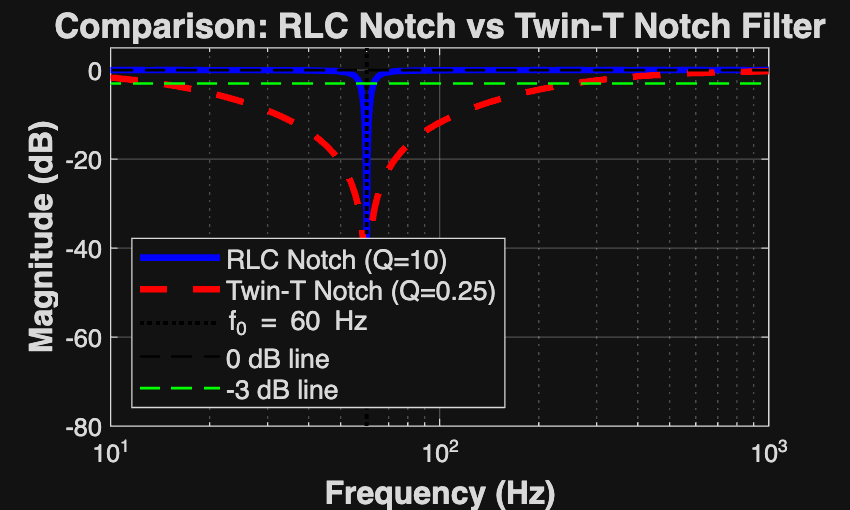

% Create Twin-T transfer function
w0_twint = 2*pi*f0_twint;
H_twint = (s^2 + w0_twint^2) / (s^2 + 4*w0_twint*s + w0_twint^2);
% Compare RLC notch with Twin-T notch
[mag_twint, ~] = bode(H_twint, w_notch);
mag_twint = squeeze(mag_twint);
mag_dB_twint = 20 * log10(mag_twint);
figure('Position', [100, 100, 1000, 600]);
semilogx(f_notch, mag_dB_notch, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f_notch, mag_dB_twint, 'r--', 'LineWidth', 2.5);
semilogx([f0_notch, f0_notch], [-80, 5], 'k:', 'LineWidth', 1.5);
semilogx([f_notch(1), f_notch(end)], [0, 0], 'k--', 'LineWidth', 1);
semilogx([f_notch(1), f_notch(end)], [-3, -3], 'g--', 'LineWidth', 1);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Comparison: RLC Notch vs Twin-T Notch Filter', 'FontSize', 13, 'FontWeight', 'bold');
legend(sprintf('RLC Notch (Q=%.0f)', Q_notch_actual), sprintf('Twin-T Notch (Q=%.2f)', Q_twint), ...
sprintf('f_0 = %.0f Hz', f0_notch), '0 dB line', '-3 dB line', ...
'Location', 'southwest', 'FontSize', 10);
ylim([-80, 5]);
xlim([10, 1000]);

## Twin-T vs RLC Notch Comparison

RLC Notch Filter:

- Advantages: High Q possible, deep notch, adjustable bandwidth

- Disadvantages: Requires inductor (bulky, expensive)

- Best for: Narrow-band rejection, high-performance applications

Twin-T Notch Filter:

- Advantages: No inductor, simple, uses only R and C

- Disadvantages: Low Q (0.25), shallow notch, wide bandwidth

- Best for: Wide-band rejection, cost-sensitive designs

For 60 Hz notch:

- RLC with Q=10: Very narrow, deep notch (~40-60 dB rejection)

- Twin-T with Q=0.25: Wide, shallow notch (~10-20 dB rejection)

## 15. Response Characteristics for Band-Pass/Band-Stop Filters

Butterworth, Chebyshev, and Bessel Characteristics

From Floyd's Section 15-2, the damping factor determines the response characteristic. For second-order band-pass and band-stop filters:

Butterworth (ζ = 0.707):

- Maximally flat passband response

- No peaking or ripple

- Damping factor DF = 1.414

- Quality factor Q = 0.707

Chebyshev (ζ < 0.707):

- Ripple in passband (for BP) or stopband (for BS)

- Steeper transition than Butterworth

- Higher Q values

- More selective response

Bessel (ζ > 0.707):

- Linear phase response

- Best time-domain characteristics

- Gentler transition

- Lower Q values Create BP filters with different characteristics for comparison

zeta_butter_bp = 1/sqrt(2);
zeta_cheby_bp = 0.5;
zeta_bessel_bp = 1.0;
% Convert to Q for band-pass
Q_butter_bp = 1/(2*zeta_butter_bp);
Q_cheby_bp = 1/(2*zeta_cheby_bp);
Q_bessel_bp = 1/(2*zeta_bessel_bp);
% Create transfer functions
H_butter_bp = (w0_bp/Q_butter_bp)*s / (s^2 + (w0_bp/Q_butter_bp)*s + w0_bp^2);
H_cheby_bp = (w0_bp/Q_cheby_bp)*s / (s^2 + (w0_bp/Q_cheby_bp)*s + w0_bp^2);
H_bessel_bp = (w0_bp/Q_bessel_bp)*s / (s^2 + (w0_bp/Q_bessel_bp)*s + w0_bp^2);
% Compute responses
[mag_butter_bp, ~] = bode(H_butter_bp, w);
[mag_cheby_bp, ~] = bode(H_cheby_bp, w);
[mag_bessel_bp, ~] = bode(H_bessel_bp, w);
mag_butter_bp = 20*log10(squeeze(mag_butter_bp));
mag_cheby_bp = 20*log10(squeeze(mag_cheby_bp));
mag_bessel_bp = 20*log10(squeeze(mag_bessel_bp));
fprintf('RESPONSE CHARACTERISTICS FOR BAND-PASS FILTERS:\n');

RESPONSE CHARACTERISTICS FOR BAND-PASS FILTERS:


fprintf('================================================\n');

fprintf('Butterworth: ζ = %.3f, Q = %.3f\n', zeta_butter_bp, Q_butter_bp);

Butterworth: ζ = 0.707, Q = 0.707


fprintf('Chebyshev-like: ζ = %.3f, Q = %.3f\n', zeta_cheby_bp, Q_cheby_bp);

Chebyshev-like: ζ = 0.500, Q = 1.000


fprintf('Bessel-like: ζ = %.3f, Q = %.3f\n\n', zeta_bessel_bp, Q_bessel_bp);

Bessel-like: ζ = 1.000, Q = 0.500



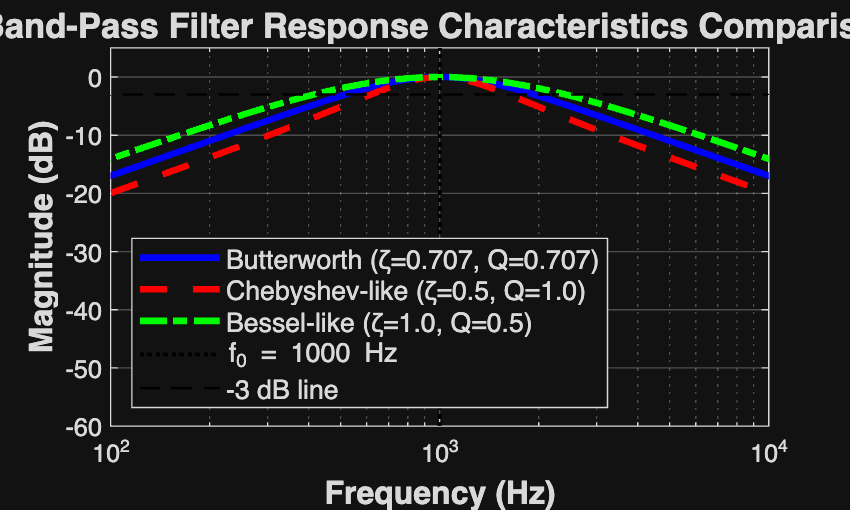

figure('Position', [100, 100, 1000, 600]);
semilogx(f, mag_butter_bp, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f, mag_cheby_bp, 'r--', 'LineWidth', 2.5);
semilogx(f, mag_bessel_bp, 'g-.', 'LineWidth', 2.5);
semilogx([f0_actual, f0_actual], [-60, 5], 'k:', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [-3, -3], 'k--', 'LineWidth', 1);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Band-Pass Filter Response Characteristics Comparison', ...
'FontSize', 13, 'FontWeight', 'bold');
legend('Butterworth (ζ=0.707, Q=0.707)', 'Chebyshev-like (ζ=0.5, Q=1.0)', ...
'Bessel-like (ζ=1.0, Q=0.5)', sprintf('f_0 = %.0f Hz', f0_actual), ...
'-3 dB line', 'Location', 'southwest', 'FontSize', 10);
ylim([-60, 5]);
xlim([100, 10000]);

## Response Characteristics Analysis

Butterworth Band-Pass:

- Flat passband, no peaking

- Moderate selectivity (Q = 0.707)

- Good all-around performance

- Most commonly used

Chebyshev-like Band-Pass:

- Higher peak at center frequency

- Sharper selectivity (Q = 1.0)

- Steeper skirts (better rejection outside passband)

- May exhibit slight peaking

Bessel-like Band-Pass:

- Broader response (Q = 0.5)

- Gentler transitions

- Best time-domain characteristics

- Lower selectivity

## 16. Practical Design Example: Audio Tone Control Filter

Design Scenario

Design a band-pass filter for a mid-range audio equalizer section:

- Center frequency: 1 kHz (mid-range)

- Bandwidth: 2 octaves (fc2 = 4×fc1)

- Butterworth response Design specifications

f0_audio = 1000;                    % 1 kHz center
octaves = 2;                        % 2 octaves bandwidth
fc2_fc1_ratio = 2^octaves;          % fc2/fc1 for 2 octaves
% Calculate critical frequencies
% For geometric mean: f0 = √(fc1×fc2) and fc2 = ratio×fc1
% Therefore: f0 = √(fc1 × ratio×fc1) = fc1×√ratio
% Solving: fc1 = f0/√ratio
fc1_audio = f0_audio / sqrt(fc2_fc1_ratio);
fc2_audio = fc1_audio * fc2_fc1_ratio;
BW_audio = fc2_audio - fc1_audio;
Q_audio = f0_audio / BW_audio;
fprintf('AUDIO MID-RANGE EQUALIZER BAND-PASS FILTER:\n');

AUDIO MID-RANGE EQUALIZER BAND-PASS FILTER:


fprintf('============================================\n');

fprintf('Center frequency f0 = %.0f Hz\n', f0_audio);

Center frequency f0 = 1000 Hz


fprintf('Lower critical frequency fc1 = %.0f Hz\n', fc1_audio);

Lower critical frequency fc1 = 500 Hz


fprintf('Upper critical frequency fc2 = %.0f Hz\n', fc2_audio);

Upper critical frequency fc2 = 2000 Hz


fprintf('Bandwidth = %.0f Hz\n', BW_audio);

Bandwidth = 1500 Hz


fprintf('Bandwidth in octaves = %.1f\n', octaves);

Bandwidth in octaves = 2.0


fprintf('Quality factor Q = %.2f (%s)\n\n', Q_audio, ...
char(ternary(Q_audio > 10, 'Narrow-band', 'Wide-band')));

Quality factor Q = 0.67 (Wide-band)



% Select components for Butterworth response
C_audio = 47e-9;                    % 47 nF
L_audio = 1 / ((2*pi*f0_audio)^2 * C_audio);
R_audio = (1/Q_audio) * sqrt(L_audio/C_audio);
fprintf('COMPONENT VALUES:\n');

COMPONENT VALUES:


fprintf('R = %.2f Ω\n', R_audio);

R = 5079.41 Ω


fprintf('L = %.3f mH\n', L_audio*1e3);

L = 538.942 mH


fprintf('C = %.0f nF\n\n', C_audio*1e9);

C = 47 nF



% Create and analyze
w0_audio = 2*pi*f0_audio;
H_audio = (w0_audio/Q_audio)*s / (s^2 + (w0_audio/Q_audio)*s + w0_audio^2);
[mag_audio, ~] = bode(H_audio, w);
mag_audio = 20*log10(squeeze(mag_audio));
% Verify bandwidth
idx_3db_lower = find(mag_audio >= max(mag_audio)-3, 1, 'first');
idx_3db_upper = find(mag_audio >= max(mag_audio)-3, 1, 'last');
fc1_verify = f(idx_3db_lower);
fc2_verify = f(idx_3db_upper);
fprintf('VERIFICATION:\n');

VERIFICATION:


fprintf('Measured fc1 = %.0f Hz (target: %.0f Hz)\n', fc1_verify, fc1_audio);

Measured fc1 = 502 Hz (target: 500 Hz)


fprintf('Measured fc2 = %.0f Hz (target: %.0f Hz)\n', fc2_verify, fc2_audio);

Measured fc2 = 1991 Hz (target: 2000 Hz)


fprintf('Measured octaves = %.2f (target: %.1f)\n', log2(fc2_verify/fc1_verify), octaves);

Measured octaves = 1.99 (target: 2.0)


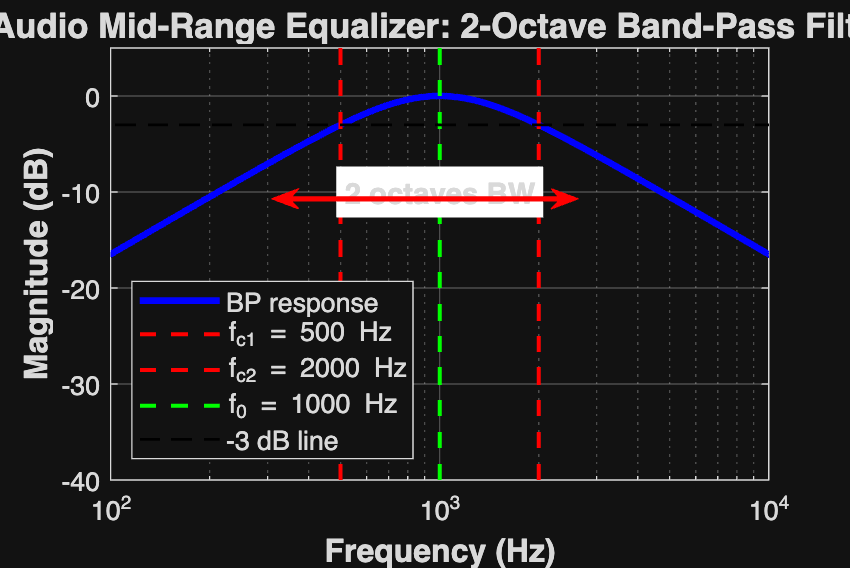

figure('Position', [100, 100, 900, 600]);
semilogx(f, mag_audio, 'b-', 'LineWidth', 2.5);
hold on;
semilogx([fc1_audio, fc1_audio], [-40, 5], 'r--', 'LineWidth', 1.5);
semilogx([fc2_audio, fc2_audio], [-40, 5], 'r--', 'LineWidth', 1.5);
semilogx([f0_audio, f0_audio], [-40, 5], 'g--', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [max(mag_audio)-3, max(mag_audio)-3], 'k--', 'LineWidth', 1);
% Add bandwidth annotation
annotation('doublearrow', [0.32, 0.68], [0.65, 0.65], 'LineWidth', 2, 'Color', 'r');
text(f0_audio, max(mag_audio)-10, '2 octaves BW', 'FontSize', 11, ...
'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'BackgroundColor', 'white');
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Audio Mid-Range Equalizer: 2-Octave Band-Pass Filter', ...
'FontSize', 13, 'FontWeight', 'bold');
legend('BP response', sprintf('f_{c1} = %.0f Hz', fc1_audio), ...
sprintf('f_{c2} = %.0f Hz', fc2_audio), sprintf('f_0 = %.0f Hz', f0_audio), ...
'-3 dB line', 'Location', 'southwest', 'FontSize', 10);
ylim([-40, 5]);
xlim([100, 10000]);

## 17. Summary Tables

Comprehensive Performance Comparison

fprintf('\n');
fprintf('========================================================================\n');

fprintf('               PASSIVE BAND-PASS AND BAND-STOP FILTERS SUMMARY\n');

               PASSIVE BAND-PASS AND BAND-STOP FILTERS SUMMARY


fprintf('========================================================================\n\n');

fprintf('BAND-PASS FILTER CONFIGURATIONS:\n');

BAND-PASS FILTER CONFIGURATIONS:


fprintf('------------------------------------------------------------------------\n');

------------------------------------------------------------------------


fprintf('Type              Center Freq      Bandwidth     Components      Q Range\n');

Type              Center Freq      Bandwidth     Components      Q Range


fprintf('------------------------------------------------------------------------\n');

------------------------------------------------------------------------


fprintf('Series RLC        f0=1/(2π√LC)     BW=f0/Q      R,L,C           Any\n');

Series RLC        f0=1/(2π√LC)     BW=f0/Q      R,L,C           Any


fprintf('Parallel RLC      f0=1/(2π√LC)     BW=f0/Q      R,L,C           Any\n');

Parallel RLC      f0=1/(2π√LC)     BW=f0/Q      R,L,C           Any


fprintf('Cascaded HP+LP    √(fc1×fc2)       fc2-fc1      2R,2C           <10\n');

Cascaded HP+LP    √(fc1×fc2)       fc2-fc1      2R,2C           <10


fprintf('------------------------------------------------------------------------\n\n');

------------------------------------------------------------------------



fprintf('BAND-STOP (NOTCH) FILTER CONFIGURATIONS:\n');

BAND-STOP (NOTCH) FILTER CONFIGURATIONS:


fprintf('------------------------------------------------------------------------\n');

------------------------------------------------------------------------


fprintf('Type              Notch Freq       Bandwidth     Components      Q Range\n');

Type              Notch Freq       Bandwidth     Components      Q Range


fprintf('------------------------------------------------------------------------\n');

------------------------------------------------------------------------


fprintf('Series RLC        f0=1/(2π√LC)     BW=f0/Q      R,L,C           Any\n');

Series RLC        f0=1/(2π√LC)     BW=f0/Q      R,L,C           Any
